# Lab 3 - SPEECH

This week we explore some basics of speech and image processing. Expository material is given to provide a background for the labs. 

We start with speech. Speech is an acoustic waveform that conveys information from a speaker to a listener. Given the importance of this form of communication, it is no surprise that many applications of signal processing have been developed to manipulate speech signals. Almost all speech processing applications currently fall into three broad categories: speech recognition, speech synthesis, and speech coding. Speech recognition may be concerned with the identification of certain words, or with the identification of the speaker. Isolated word recognition algorithms attempt to identify individual words, such as in automated telephone services. Automatic speech recognition systems attempt to recognize continuous spoken language, possibly to convert into text within a word processor. These systems often incorporate grammatical cues to increase their accuracy. Speaker identification is mostly used in security applications, as a person’s voice is much like a “fingerprint”. The objective in speech synthesis is to convert a string of text, or a sequence of words, into natural-sounding speech. One example is the Speech Plus synthesizer used by the late Stephen Hawking (although it unfortunately gives him a machine-like American accent). There are also similar systems which read text for the blind. Speech synthesis has also been used to aid scientists in learning about the mechanisms of human speech production, and thereby in the treatment of speech-related disorders. Speech coding is mainly concerned with exploiting certain redundancies of the speech signal, allowing it to be represented in a compressed form. Much of the research in speech compression has been motivated by the need to conserve bandwidth in communication systems. For example, speech coding is used to reduce the bit rate in digital cellular systems.

### Time-Domain Speech Processing

#### Speech Production

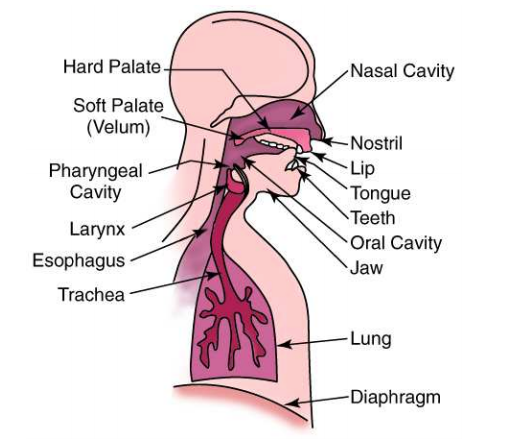

Speech consists of acoustic pressure waves created by the voluntary movements of anatomical structures in the human speech production system, shown in the figure above. As the diaphragm forces air through the system, these structures are able to generate and shape a wide variety of waveforms. These waveforms can be broadly categorized into voiced and unvoiced speech. Voiced sounds, vowels for example, are produced by forcing air through the larynx, with the tension of the vocal cords adjusted so that they vibrate in a relaxed oscillation. This produces quasi-periodic pulses of air which are acoustically filtered as they propagate through the vocal tract, and possibly through the nasal cavity. The shape of the cavities that comprise the vocal tract, known as the area function, determines the natural frequencies, or formants, which are emphasized in the speech waveform. The period of the excitation, known as the pitch period, is generally small with respect to the rate at which the vocal tract changes shape. Therefore, a segment of voiced speech covering several pitch periods will appear somewhat periodic. Average values for the pitch period are around 8 ms for male speakers, and 4 ms for female speakers.

In contrast, unvoiced speech has more of a noise-like quality. Unvoiced sounds are usually much smaller in amplitude, and oscillate much faster than voiced speech. These sounds are generally produced by turbulence, as air is forced through a constriction at some point in the vocal tract. For example, an h sound comes from a constriction at the vocal cords, and an f is generated by a constriction at the lips. An illustrative example of voiced and unvoiced sounds contained in the word “erase” are shown in the figure below. The original utterance is shown in (a). The voiced segment in (b) is a time magnification of the “a” portion of the word. Notice the highly periodic nature of this segment. The fundamental period of this waveform, which is about 8.5 ms here, is called the pitch period. The unvoiced segment in (c) comes from the “s” sound at the end of the word. This waveform is much more noise-like than the voiced segment, and is much smaller in magnitude.

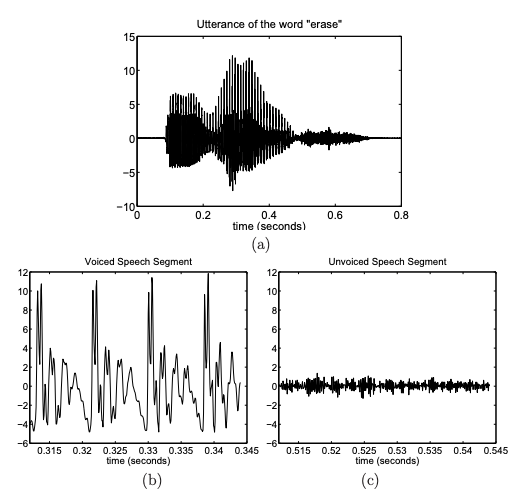

### Classification of Voiced/Unvoiced Speech

For many speech processing algorithms, a very important step is to determine the type of sound that is being uttered in a given time frame. In this section, we will introduce two simple methods for discriminating between voiced and unvoiced speech.

Read in the speech signal 'Start.wav'; plot the signal; and listen to the signal.

**Put your code here:**

Identify two segments of the speech signal: one signal that is voiced and another segment that is unvoiced.  Save 300 samples from the voiced segment of speech into a variable called voiceSig. Save 300 samples from the unvoiced segment of speech into a variable called unVoiceSig. Use the subplot command to plot these two segments in a single figure. Make sure you have a time axis that matches that of the orignal signal.

**Put your code here:**

Use the MATLAB function to find the primary peaks in the voiced speech signal. Read MATLAB's help for the findpeaks function by typing into the command window: 'help findpeaks'. Run the findpeaks function twice: once to plot the peaks and ensure you only take the correct peaks and once to grab the peak sample locations. Calculate the voiced speech pitch period in ms and pitch frequency. Determine whether the talker is likely a male or female. 

**Put your code here:**

**Put your answers here:**

The voiced speech pitch period is about ____ ms.

The voiced speech pitch frequency is about ____ Hz.

Talker is likely a ____. 

One way to categorize speech segments is to compute the average energy. Recall this is defined by the following:


$$P = \frac{1}{N}\sum_{n=1}^{N}x^{2}[n]\ \text{.}$$


Compute the average energy of the voiced and unvoiced segments that you plotted above. For which segment is the average energy greater?

**Put your code here:**

**Put your answer here:**

The voiced/unvoiced speech has greater average energy.

While signal energy may be one method to distinguish between voiced speech and unvoiced speech, it is generally unreliable because talkers vary the loudness of their speech. Another method for discriminating between voiced and unvoiced segments is to determine the rate at which the waveform oscillates by counting number of zero-crossings that occur within a frame (the number of times the signal changes sign). Write a function ZeroCross that will compute the number of zero-crossings that occur within a vector, and apply this to the two vectors VoicedSig and UnvoicedSig. Which segment has more zero-crossings? 

**Put your ZeroCross function here:**

**Put your code here:**

**Put your answer here:**

The voiced/unvoiced speech segment has more zero crossings.

### Phonemes

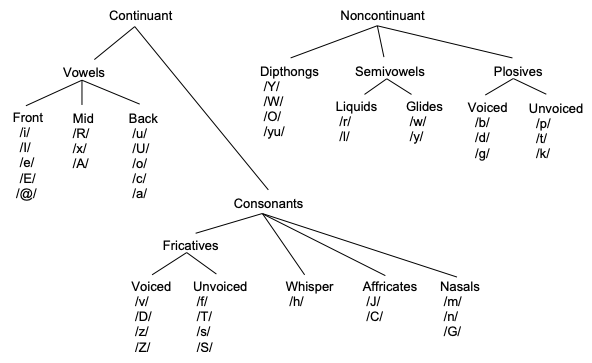

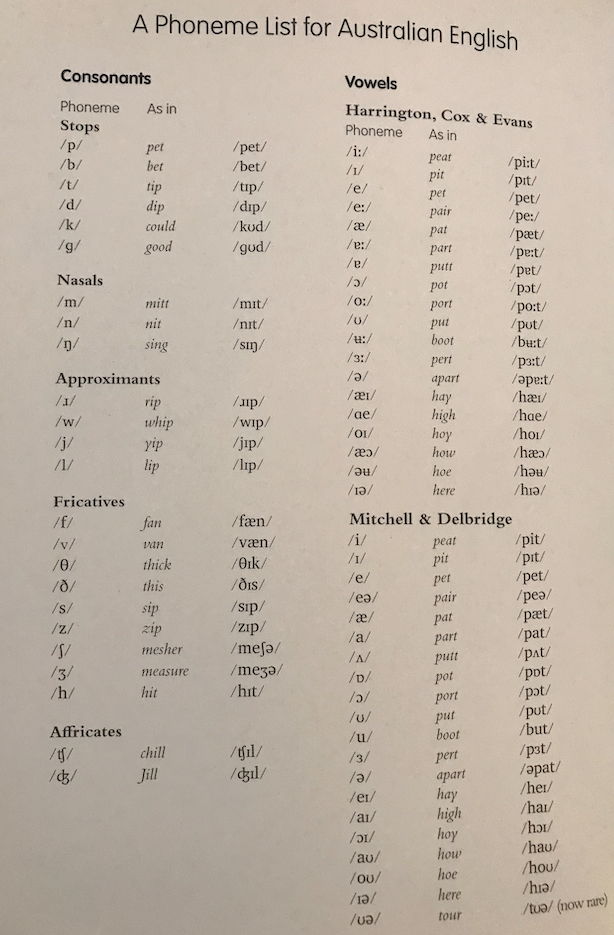

English can be described in terms of a set of about 42 distinct sounds called phonemes, illustrated in the two figures above. They can be classified in many ways according to their distinguishing properties. Vowels are formed by exciting a fixed vocal tract with quasiperiodic pulses of air. Fricatives are produced by forcing air through a constriction (usually towards the mouth end of the vocal tract), causing turbulent air flow. Fricatives may be voiced or unvoiced. Plosive sounds are created by making a complete closure, typically at the frontal vocal tract, building up pressure behind the closure and abruptly releasing it. A diphthong is a gliding monosyllabic sound that starts at or near the articulatory position for one vowel, and moves toward the position of another. It can be a very insightful exercise to recite the phonemes shown in the figures above (one is for American English and the other is for Australian English), and make a note of the movements you are making to create them.

### Speech Model

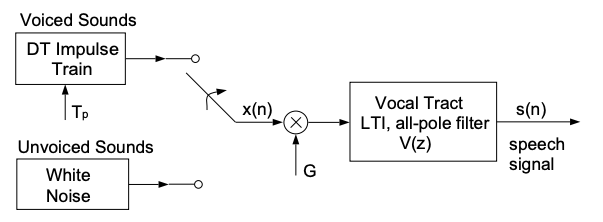

From a signal processing standpoint, it is very useful to think of speech production in terms of a model, as in the figure above. The model shown is the simplest of its kind, but it includes all the principal components. The excitations for voiced and unvoiced speech are represented by an impulse train and white noise generator, respectively. The pitch of voiced speech is controlled by the spacing between impulses, Tp, and the amplitude (volume) of the excitation is controlled by the gain factor G. As the acoustical excitation travels from its source (vocal cords, or a constriction), the shape of the vocal tract alters the spectral content of the signal. The most prominent effect is the formation of resonances, which intensifies the signal energy at certain frequencies (called formants). The amplification of certain frequencies may be achieved with a linear filter by an appropriate placement of poles in the transfer function. This is why the filter in our speech model utilizes an all-pole LTI filter. A more accurate model might include a few zeros in the transfer function, but if the order of the filter is chosen appropriately, the all-pole model is sufficient. The primary reason for using the all-pole model is the distinct computational advantage in calculating the filter coefficients. Recall that the transfer function of an all-pole filter has the form:


$$V(z) = \frac{1}{1 - \sum_{k=1}^{P}a_kz^{-k}\ \text{.}$$


where P is the order of the filter. This is an IIR filter that may be implemented with a recursive difference equation. With the input G·x[n], the speech signal s[n] may be written as:


$$s[n] = \sum_{k=1}^{P}a_ks[n-k]+G\cdot x[n] \ \text{.}$$


Keep in mind that the filter coefficients will change continuously as the shape of the vocal tract changes, but speech segments of an appropriately small length may be approximated by a time-invariant model. This speech model is used in a variety of speech processing applications, including methods of speech recognition, speech coding for transmission, and speech synthesis. Each of these applications of the model involves dividing the speech signal into short segments, over which the filter coefficients are almost constant. For example, in speech transmission the bit rate can be significantly reduced by dividing the signal up into segments, computing and sending the model parameters for each segment (filter coefficients, gain, etc.), and re-synthesizing the signal at the receiving end, using a model similar to that in the figure shown above. Most telephone systems use some form of this approach. Another example is speech recognition. Most recognition methods involve comparisons between short segments of the speech signals, and the filter coefficients of this model are often used in computing the “difference” between segments.

### Synthesis of Voiced Speech

Download the file coeff.mat and load it into the Matlab workspace using the load command. This will load three sets of filter coefficients: A1, A2, and A3 for the vocal tract model described above. Each vector contains coefficients {a1,a2,... ,a15} for an all-pole filter of order 15. We will now synthesize voiced speech segments for each of these sets of coefficients. First write a MATLAB function 

sig =ExciteV(lenN, periodNp) 

which creates a length N excitation for voiced speech, with a pitch period of Np samples. The output vector x should contain a discrete time impulse train with period Np (e.g. [1 0 0 · · · 0 1 0 0 · · ·]). Assuming a sampling frequency of 8 kHz (0.125 ms/sample), create a 40 millisecond long excitation with a pitch period of 8 ms. Flter the excitation signal for each set of IIR coefficients using the MATLAB filter function. Plot each of the three filtered signals using the MATLAB function subplot() to plot them in the same figure. 

**Put your ExciteV function code here:**

**Put your code here:**

We will now compute the frequency response of each of these filters. The frequency response may be obtained by evaluating $V(z)$ at $z = e^{j\,\omega}$. Evaluate this manually and compare with the MATLAB function freqz().  Plot the magnitude of each response versus frequency in Hertz. Use subplot() to plot them in the same figure. You should have six plots, three using your own code and three using freqz().

**Put your code here:**

Use MATLAB's function findpeaks to find the peaks in the spectal response. What are the first three forments for each simulated vowel sound (to the nearest Hz)?

**Put your code to find the peaks here:**

**Put your answer here:**

A1: formant frequencies: ___ Hz, ____ Hz, ____ Hz

A2: formant frequencies: ____ Hz, ____ Hz, ____ Hz

A3: formant frequencies: ____ Hz, ____ Hz, ____ Hz

Create a 1 - 2 second excitation signal and listen to the simulated vowel sound. Try to determine the identity of each vowel.

**Put your code here:**

**Put your answer here:**

Vowel 1 is ________ sound.

Vowel 2 is a _______ sound.

Vowel 3 is a _______ sound.